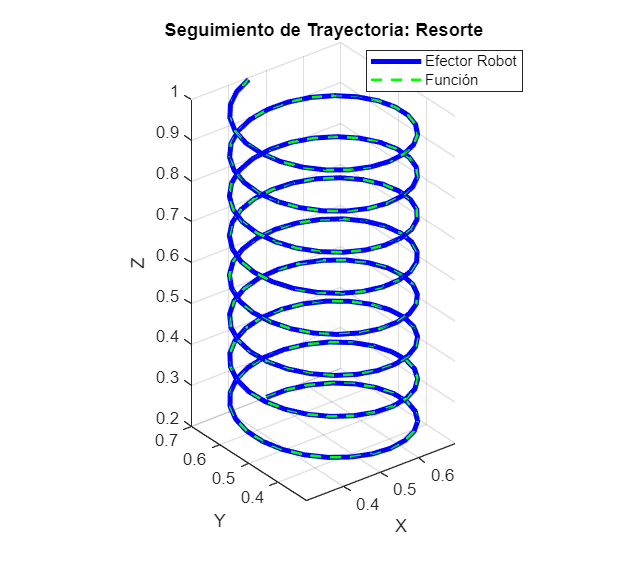

%% Seguimiento de Trayectorias 3D - Robot Antropomórfico 3GDL
clc; clear; close all;

% Parámetros físicos del Robot
B1 = 0.1; B2 = 0.1; B3 = 0.1;
l1 = 0.5; l2 = 0.7; l3 = 0.6;

%% ==========================================================
%  TRAYECTORIA 1: RESORTE
%  ==========================================================
t_res = 0:0.05:10;
xc = 0.5; yc = 0.5; 
r_res = 0.2;

x_res = xc + (r_res .* sin(t_res * 5));
y_res = yc + (r_res .* cos(t_res * 5));
z_res = 0.2 + (t_res * 0.08);

N_res = length(t_res);
x0_res = zeros(1, N_res); y0_res = zeros(1, N_res); z0_res = zeros(1, N_res);
q1_res = zeros(1, N_res); q2_res = zeros(1, N_res); q3_res = zeros(1, N_res);

for i = 1:N_res
    [q1_res(i), q2_res(i), q3_res(i)] = cinv_R3gdl(B1, B2, B3, l1, l2, l3, x_res(i), y_res(i), z_res(i));
    [x0_res(i), y0_res(i), z0_res(i)] = cdir_Antropomorfico(q1_res(i), q2_res(i), q3_res(i), l1, l2, l3, B1, B2, B3);
end

% Gráfica 3D
figure('Name', 'Trayectoria 1: Resorte (3D)', 'Position', [50, 500, 500, 450]);
plot3(x0_res, y0_res, z0_res, 'b', 'LineWidth', 3); hold on;
plot3(x_res, y_res, z_res, '--g', 'LineWidth', 1.5);
axis equal; grid on; title('Seguimiento de Trayectoria: Resorte');
legend("Efector Robot", "Función", 'Location', 'best'); xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

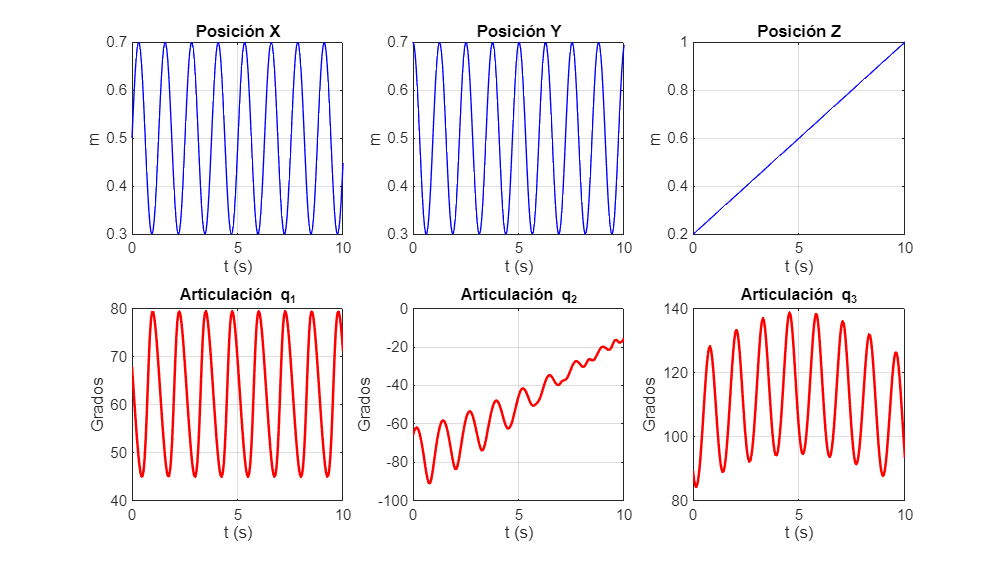


% Análisis Temporal
plotAnalisisTemporal(t_res, x_res, y_res, z_res, x0_res, y0_res, z0_res, q1_res, q2_res, q3_res, 'Resorte');

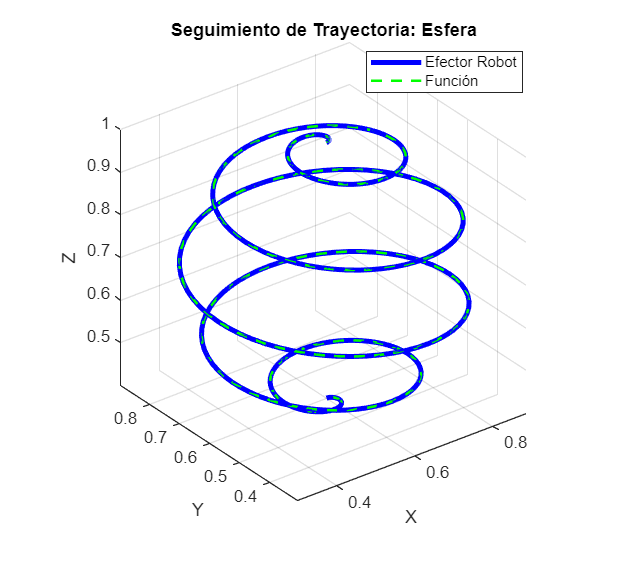


%% ==========================================================
%  TRAYECTORIA 2: ESFERA
%  ==========================================================
t_esf = 0:0.01:pi;
x_esf = 0.3 .* sin(t_esf) .* cos(10 * t_esf) + 0.6;
y_esf = 0.3 .* sin(t_esf) .* sin(10 * t_esf) + 0.6;
z_esf = 0.3 .* cos(t_esf) + 0.7;

N_esf = length(t_esf);
x0_esf = zeros(1, N_esf); y0_esf = zeros(1, N_esf); z0_esf = zeros(1, N_esf);
q1_esf = zeros(1, N_esf); q2_esf = zeros(1, N_esf); q3_esf = zeros(1, N_esf);

for i = 1:N_esf
    [q1_esf(i), q2_esf(i), q3_esf(i)] = cinv_R3gdl(B1, B2, B3, l1, l2, l3, x_esf(i), y_esf(i), z_esf(i));
    [x0_esf(i), y0_esf(i), z0_esf(i)] = cdir_Antropomorfico(q1_esf(i), q2_esf(i), q3_esf(i), l1, l2, l3, B1, B2, B3);
end

% Gráfica 3D
figure('Name', 'Trayectoria 2: Esfera (3D)', 'Position', [50, 50, 500, 450]);
plot3(x0_esf, y0_esf, z0_esf, 'b', 'LineWidth', 3); hold on;
plot3(x_esf, y_esf, z_esf, '--g', 'LineWidth', 1.5);
axis equal; grid on; title('Seguimiento de Trayectoria: Esfera');
legend("Efector Robot", "Función", 'Location', 'best'); xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

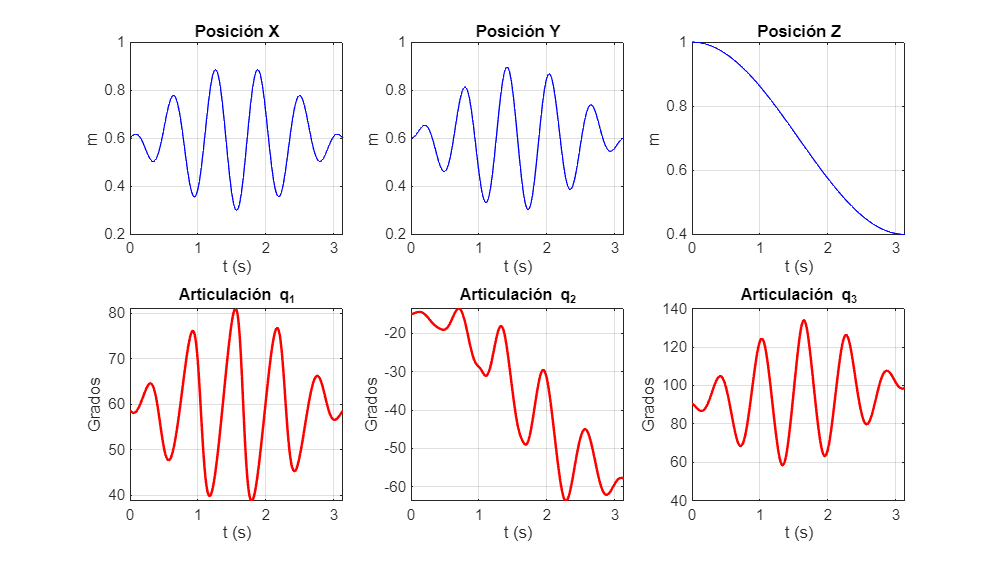


% Análisis Temporal
plotAnalisisTemporal(t_esf, x_esf, y_esf, z_esf, x0_esf, y0_esf, z0_esf, q1_esf, q2_esf, q3_esf, 'Esfera');

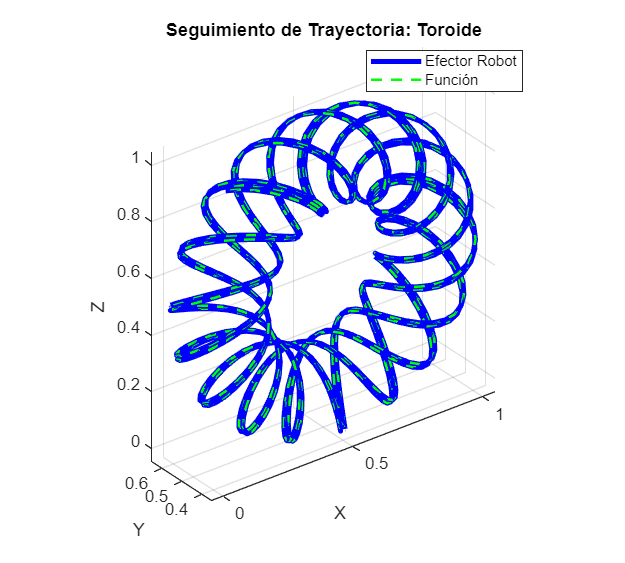


%% ==========================================================
%  TRAYECTORIA 3: TOROIDE
%  ==========================================================
t_tor = 0:0.05:40;
x_tor = (0.4 + 0.15 .* cos(sqrt(32) .* t_tor)) .* cos(t_tor) + 0.5;
y_tor = 0.15 .* sin(sqrt(32) .* t_tor) + 0.5;
z_tor = (0.4 + 0.15 .* cos(sqrt(32) .* t_tor)) .* sin(t_tor) + 0.5;

N_tor = length(t_tor);
x0_tor = zeros(1, N_tor); y0_tor = zeros(1, N_tor); z0_tor = zeros(1, N_tor);
q1_tor = zeros(1, N_tor); q2_tor = zeros(1, N_tor); q3_tor = zeros(1, N_tor);

for i = 1:N_tor
    [q1_tor(i), q2_tor(i), q3_tor(i)] = cinv_R3gdl(B1, B2, B3, l1, l2, l3, x_tor(i), y_tor(i), z_tor(i));
    [x0_tor(i), y0_tor(i), z0_tor(i)] = cdir_Antropomorfico(q1_tor(i), q2_tor(i), q3_tor(i), l1, l2, l3, B1, B2, B3);
end

% Gráfica 3D
figure('Name', 'Trayectoria 3: Toroide (3D)', 'Position', [50, 500, 500, 450]);
plot3(x0_tor, y0_tor, z0_tor, 'b', 'LineWidth', 3); hold on;
plot3(x_tor, y_tor, z_tor, '--g', 'LineWidth', 1.5);
axis equal; grid on; title('Seguimiento de Trayectoria: Toroide');
legend("Efector Robot", "Función", 'Location', 'best'); xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

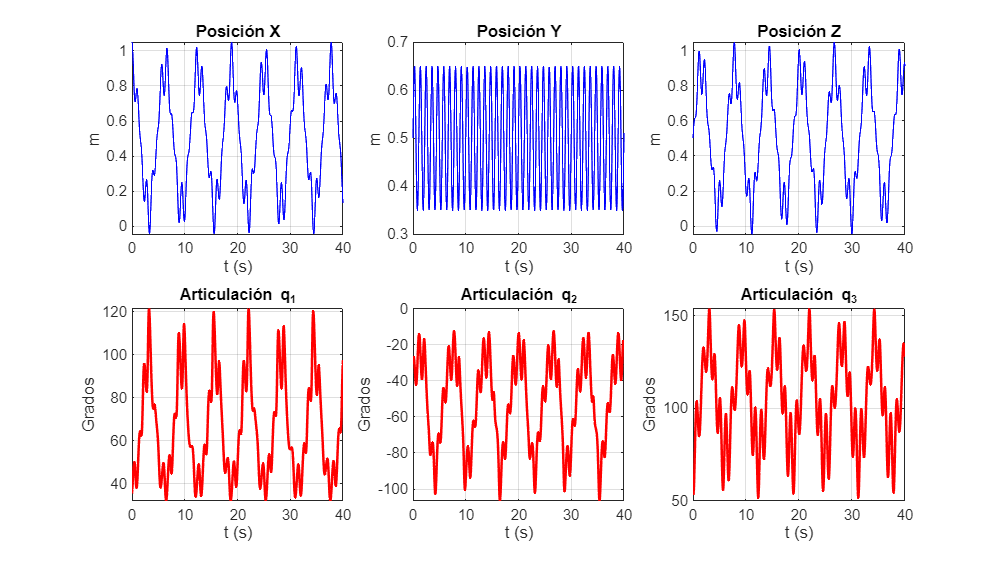


% Análisis Temporal
plotAnalisisTemporal(t_tor, x_tor, y_tor, z_tor, x0_tor, y0_tor, z0_tor, q1_tor, q2_tor, q3_tor, 'Toroide');

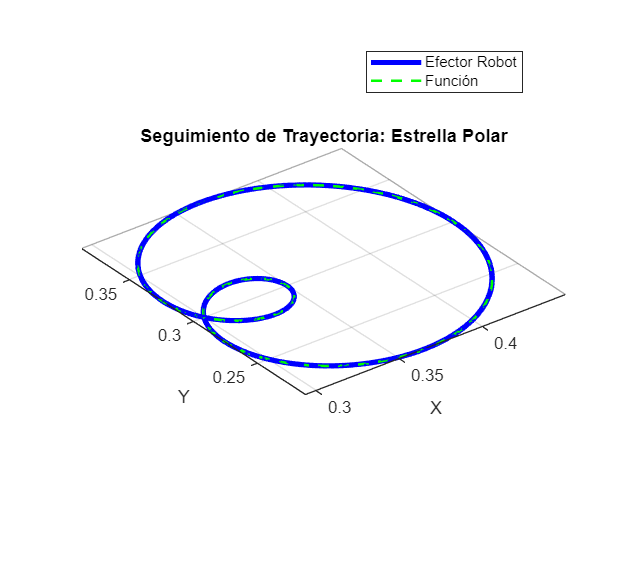


%% ==========================================================
%  TRAYECTORIA 4: ESTRELLA POLAR
%  ==========================================================
t_pol = 0:0.1:30;
xc = 0.3; yc = 0.3;
r_pol = 0.05 + 0.1 .* sin(t_pol);

x_pol = xc + r_pol .* sin(t_pol);
y_pol = yc + r_pol .* cos(t_pol);
z_pol = (l1 + B1 + 0.05) .* ones(1, length(t_pol));

N_pol = length(t_pol);
x0_pol = zeros(1, N_pol); y0_pol = zeros(1, N_pol); z0_pol = zeros(1, N_pol);
q1_pol = zeros(1, N_pol); q2_pol = zeros(1, N_pol); q3_pol = zeros(1, N_pol);

for i = 1:N_pol
    [q1_pol(i), q2_pol(i), q3_pol(i)] = cinv_R3gdl(B1, B2, B3, l1, l2, l3, x_pol(i), y_pol(i), z_pol(i));
    [x0_pol(i), y0_pol(i), z0_pol(i)] = cdir_Antropomorfico(q1_pol(i), q2_pol(i), q3_pol(i), l1, l2, l3, B1, B2, B3);
end

% Gráfica 3D
figure('Name', 'Trayectoria 4: Estrella Polar (3D)', 'Position', [50, 50, 500, 450]);
plot3(x0_pol, y0_pol, z0_pol, 'b', 'LineWidth', 3); hold on;
plot3(x_pol, y_pol, z_pol, '--g', 'LineWidth', 1.5);
axis equal; grid on; title('Seguimiento de Trayectoria: Estrella Polar');
legend("Efector Robot", "Función", 'Location', 'best'); xlabel('X'); ylabel('Y'); zlabel('Z'); view(3);

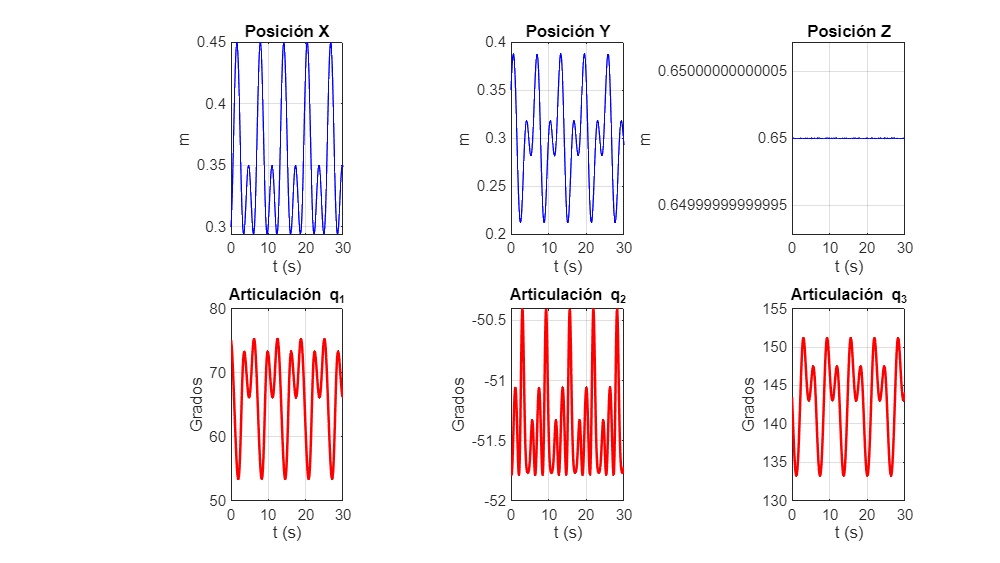


% Análisis Temporal
plotAnalisisTemporal(t_pol, x_pol, y_pol, z_pol, x0_pol, y0_pol, z0_pol, q1_pol, q2_pol, q3_pol, 'Estrella Polar');

function plotAnalisisTemporal(t, x, y, z, x0, y0, z0, q1, q2, q3, titulo)
    % Crea una figura con 6 subgráficas comparando coordenadas y perfiles articulares
    figure('Name', ['Análisis Temporal: ', titulo], 'Position', [600, 500, 800, 450]);
    
    subplot(2,3,1); plot(t, x, '--g', t, x0, 'b'); 
    title('Posición X'); xlabel('t (s)'); ylabel('m'); grid on;
    
    subplot(2,3,2); plot(t, y, '--g', t, y0, 'b'); 
    title('Posición Y'); xlabel('t (s)'); ylabel('m'); grid on;
    
    subplot(2,3,3); plot(t, z, '--g', t, z0, 'b'); 
    title('Posición Z'); xlabel('t (s)'); ylabel('m'); grid on;
    
    subplot(2,3,4); plot(t, q1, 'r', 'LineWidth', 1.5); 
    title('Articulación q_1'); xlabel('t (s)'); ylabel('Grados'); grid on;
    
    subplot(2,3,5); plot(t, q2, 'r', 'LineWidth', 1.5); 
    title('Articulación q_2'); xlabel('t (s)'); ylabel('Grados'); grid on;
    
    subplot(2,3,6); plot(t, q3, 'r', 'LineWidth', 1.5); 
    title('Articulación q_3'); xlabel('t (s)'); ylabel('Grados'); grid on;
end